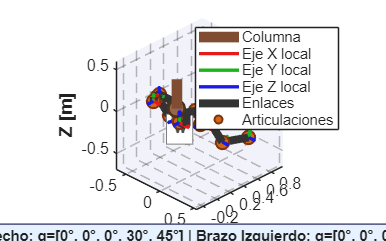

close all; clear all; clc

%% Parámetros de longitud
L1 = 0.1;
L2 = 0.15;
L3 = 0.08;
L4 = 0.2;
L5 = 0.08;
L6 = 0.05;
L7 = 0.05;
L8 = 0.1;
L9 = 0.35;
L10 = 0.4;

%% Configuración inicial BRAZO DERECHO (convertir de grados a radianes)
q1_R = deg2rad(0);
q2_R = deg2rad(0);
q3_R = deg2rad(0);
q4_R = deg2rad(30);
q5_R = deg2rad(45);

%% Configuración inicial BRAZO IZQUIERDO (puede ser igual o diferente)
q1_L = deg2rad(0);
q2_L = deg2rad(0);
q3_L = deg2rad(0);
q4_L = deg2rad(30);
q5_L = deg2rad(45);

%% Función para crear matriz DH estándar
dh_standard = @(theta, d, a, alpha) [
    cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
    sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
    0,           sin(alpha),              cos(alpha),            d;
    0,           0,                       0,                     1
];

%% ==================== BRAZO DERECHO ====================
%% Transformaciones locales BRAZO DERECHO
T0_w_R = [[1 0 0; 0 0 -1; 0 1 0], [0; 0; 0]; 0 0 0 1];
Ta_0_R = dh_standard(q1_R, 0, L1, 0);
Tb_a_R = [eye(3), [0; L2; 0]; 0 0 0 1];
Tc_b_R = [eye(3), [0; 0; -L3]; 0 0 0 1];
T1_c_R = [[0 1 0; 0 0 1; 1 0 0], [L4; 0; 0]; 0 0 0 1];
Td_1_R = dh_standard(q2_R, 0, L5, 0);
T2_d_R = [[0 0 1; 1 0 0; 0 1 0], [0; 0; -L6]; 0 0 0 1];
Te_2_R = dh_standard(q3_R, 0, L7, 0);
T3_e_R = [[0 0 1; -1 0 0; 0 -1 0], [0; 0; -L8]; 0 0 0 1];
T4_3_R = dh_standard(q4_R, 0, L9, 0);
T5_4_R = dh_standard(q5_R, 0, L10, 0);

%% Calcular transformaciones BRAZO DERECHO respecto a {w}
Tw_w = eye(4);
T0_w_world_R = T0_w_R;
Ta_w_world_R = T0_w_world_R * Ta_0_R;
Tb_w_world_R = Ta_w_world_R * Tb_a_R;
Tc_w_world_R = Tb_w_world_R * Tc_b_R;
T1_w_world_R = Tc_w_world_R * T1_c_R;
Td_w_world_R = T1_w_world_R * Td_1_R;
T2_w_world_R = Td_w_world_R * T2_d_R;
Te_w_world_R = T2_w_world_R * Te_2_R;
T3_w_world_R = Te_w_world_R * T3_e_R;
T4_w_world_R = T3_w_world_R * T4_3_R;
T5_w_world_R = T4_w_world_R * T5_4_R;

%% Extraer posiciones BRAZO DERECHO
all_frames_R = {Tw_w, T0_w_world_R, Ta_w_world_R, Tb_w_world_R, Tc_w_world_R, T1_w_world_R, ...
                Td_w_world_R, T2_w_world_R, Te_w_world_R, T3_w_world_R, T4_w_world_R, T5_w_world_R};
all_positions_R = zeros(12, 3);
for i = 1:12
    all_positions_R(i, :) = all_frames_R{i}(1:3, 4)';
end

numbered_frames_R = {Tw_w, T0_w_world_R, T1_w_world_R, T2_w_world_R, T3_w_world_R, T4_w_world_R, T5_w_world_R};
numbered_indices_R = [1, 2, 6, 8, 10, 11, 12];

%% ==================== BRAZO IZQUIERDO (ESPEJO) ====================
%% Frame 0 del brazo izquierdo desplazado -8cm en X del sistema mundo
T0_offset_L = eye(4);
T0_offset_L(1, 4) = -0.08; % Desplazamiento de -8 cm en X

%% Transformaciones locales BRAZO IZQUIERDO (ESPEJO del derecho)
% La cinemática es espejo, entonces las coordenadas Y se invierten
T0_w_L = [[1 0 0; 0 0 -1; 0 1 0], [0; 0; 0]; 0 0 0 1];
Ta_0_L = dh_standard(q1_L, 0, -L1, 0);
Tb_a_L = [eye(3), [0; L2; 0]; 0 0 0 1];
Tc_b_L = [eye(3), [0; 0; -L3]; 0 0 0 1];
T1_c_L = [[0 1 0; 0 0 1; 1 0 0], [-L4; 0; 0]; 0 0 0 1];
Td_1_L = dh_standard(q2_L, 0, L5, 0);
T2_d_L = [[0 0 1; 1 0 0; 0 1 0], [0; 0; -L6]; 0 0 0 1];
Te_2_L = dh_standard(q3_L, 0, -L7, 0);
T3_e_L = [[0 0 1; -1 0 0; 0 -1 0], [0; 0; -L8]; 0 0 0 1];
T4_3_L = dh_standard(q4_L, 0, L9, 0);
T5_4_L = dh_standard(q5_L, 0, L10, 0);

%% Calcular transformaciones BRAZO IZQUIERDO respecto a {w}
T0_w_world_L = T0_offset_L * T0_w_L;
Ta_w_world_L = T0_w_world_L * Ta_0_L;
Tb_w_world_L = Ta_w_world_L * Tb_a_L;
Tc_w_world_L = Tb_w_world_L * Tc_b_L;
T1_w_world_L = Tc_w_world_L * T1_c_L;
Td_w_world_L = T1_w_world_L * Td_1_L;
T2_w_world_L = Td_w_world_L * T2_d_L;
Te_w_world_L = T2_w_world_L * Te_2_L;
T3_w_world_L = Te_w_world_L * T3_e_L;
T4_w_world_L = T3_w_world_L * T4_3_L;
T5_w_world_L = T4_w_world_L * T5_4_L;

%% Extraer posiciones BRAZO IZQUIERDO
all_frames_L = {T0_offset_L, T0_w_world_L, Ta_w_world_L, Tb_w_world_L, Tc_w_world_L, T1_w_world_L, ...
                Td_w_world_L, T2_w_world_L, Te_w_world_L, T3_w_world_L, T4_w_world_L, T5_w_world_L};
all_positions_L = zeros(12, 3);
for i = 1:12
    all_positions_L(i, :) = all_frames_L{i}(1:3, 4)';
end

numbered_frames_L = {T0_offset_L, T0_w_world_L, T1_w_world_L, T2_w_world_L, T3_w_world_L, T4_w_world_L, T5_w_world_L};
numbered_indices_L = [1, 2, 6, 8, 10, 11, 12];

%% ==================== VISUALIZACIÓN ====================
fig = figure('Color', 'w', 'Position', [100, 100, 1600, 1000]);
hold on; grid on; axis equal;

% Configurar vista y estilo
view(45, 30);
xlabel('X [m]', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Y [m]', 'FontSize', 14, 'FontWeight', 'bold');
zlabel('Z [m]', 'FontSize', 14, 'FontWeight', 'bold');
%title('Exoesqueleto - Visualización 3D (Ambos Brazos)', 'FontSize', 16, 'FontWeight', 'bold');

grid on;
set(gca, 'GridAlpha', 0.3, 'GridLineStyle', '--');
set(gca, 'FontSize', 12);
set(gca, 'Color', [0.95 0.95 0.98]);

%% Dibujar COLUMNA VERTEBRAL (línea vertical en X = -4cm)
spine_x = -0.04;
spine_z_min = -0.2;
spine_z_max = 0.5;
plot3([spine_x, spine_x], [0, 0], [spine_z_min, spine_z_max], ...
      'Color', [0.5 0.3 0.2], 'LineWidth', 8, 'LineStyle', '-');

% Añadir marcador en la columna
scatter3(spine_x, 0, (spine_z_min + spine_z_max)/2, 150, ...
         'MarkerFaceColor', [0.6 0.4 0.3], 'MarkerEdgeColor', [0.3 0.2 0.1], 'LineWidth', 2);

%% Colores y parámetros (MISMO DISEÑO PARA AMBOS BRAZOS)
link_color = [0.2 0.2 0.2]; % Negro oscuro
link_width = 6;

joint_color = [0.8 0.4 0.1]; % Naranja
joint_size = 100;

axis_length = 0.08;
axis_width = 2.5;
colors_x = [0.9 0.1 0.1];  % Rojo para X
colors_y = [0.1 0.7 0.1];  % Verde para Y
colors_z = [0.1 0.1 0.9];  % Azul para Z

%% ==================== DIBUJAR BRAZO DERECHO ====================
% Enlaces
for i = 1:size(all_positions_R, 1)-1
    plot3([all_positions_R(i,1), all_positions_R(i+1,1)], ...
          [all_positions_R(i,2), all_positions_R(i+1,2)], ...
          [all_positions_R(i,3), all_positions_R(i+1,3)], ...
          'Color', link_color, 'LineWidth', link_width);
end

% Articulaciones
numbered_positions_R = zeros(7, 3);
for i = 1:7
    numbered_positions_R(i, :) = all_positions_R(numbered_indices_R(i), :);
end
scatter3(numbered_positions_R(2:end,1), numbered_positions_R(2:end,2), numbered_positions_R(2:end,3), ...
         joint_size, 'MarkerFaceColor', joint_color, ...
         'MarkerEdgeColor', [0.5 0.2 0.05], 'LineWidth', 1.5);

% Ejes de coordenadas (solo frames numerados, excepto {w})
frame_names_R = {'0_R', '1_R', '2_R', '3_R', '4_R', '5_R'};
for i = 2:7
    T = numbered_frames_R{i};
    origin = T(1:3, 4);
    x_axis = T(1:3, 1);
    y_axis = T(1:3, 2);
    z_axis = T(1:3, 3);
    
    quiver3(origin(1), origin(2), origin(3), ...
            x_axis(1)*axis_length, x_axis(2)*axis_length, x_axis(3)*axis_length, ...
            'Color', colors_x, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    quiver3(origin(1), origin(2), origin(3), ...
            y_axis(1)*axis_length, y_axis(2)*axis_length, y_axis(3)*axis_length, ...
            'Color', colors_y, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    quiver3(origin(1), origin(2), origin(3), ...
            z_axis(1)*axis_length, z_axis(2)*axis_length, z_axis(3)*axis_length, ...
            'Color', colors_z, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    % text(origin(1), origin(2), origin(3)+0.05, frame_names_R{i-1}, ...
    %      'FontSize', 10, 'FontWeight', 'bold', 'Color', [0.3 0.3 0.5], ...
    %      'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1 0.7], ...
    %      'EdgeColor', [0.5 0.5 0.5], 'Margin', 3);
end

%% ==================== DIBUJAR BRAZO IZQUIERDO ====================
% Enlaces
for i = 1:size(all_positions_L, 1)-1
    plot3([all_positions_L(i,1), all_positions_L(i+1,1)], ...
          [all_positions_L(i,2), all_positions_L(i+1,2)], ...
          [all_positions_L(i,3), all_positions_L(i+1,3)], ...
          'Color', link_color, 'LineWidth', link_width);
end

% Articulaciones
numbered_positions_L = zeros(7, 3);
for i = 1:7
    numbered_positions_L(i, :) = all_positions_L(numbered_indices_L(i), :);
end
scatter3(numbered_positions_L(2:end,1), numbered_positions_L(2:end,2), numbered_positions_L(2:end,3), ...
         joint_size, 'MarkerFaceColor', joint_color, ...
         'MarkerEdgeColor', [0.5 0.2 0.05], 'LineWidth', 1.5);

% Ejes de coordenadas (solo frames numerados, excepto punto de offset)
frame_names_L = {'0_L', '1_L', '2_L', '3_L', '4_L', '5_L'};
for i = 2:7
    T = numbered_frames_L{i};
    origin = T(1:3, 4);
    x_axis = T(1:3, 1);
    y_axis = T(1:3, 2);
    z_axis = T(1:3, 3);
    
    quiver3(origin(1), origin(2), origin(3), ...
            x_axis(1)*axis_length, x_axis(2)*axis_length, x_axis(3)*axis_length, ...
            'Color', colors_x, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    quiver3(origin(1), origin(2), origin(3), ...
            y_axis(1)*axis_length, y_axis(2)*axis_length, y_axis(3)*axis_length, ...
            'Color', colors_y, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    quiver3(origin(1), origin(2), origin(3), ...
            z_axis(1)*axis_length, z_axis(2)*axis_length, z_axis(3)*axis_length, ...
            'Color', colors_z, 'LineWidth', axis_width, 'MaxHeadSize', 1.5, 'AutoScale', 'off');
    
    % text(origin(1), origin(2), origin(3)+0.05, frame_names_L{i-1}, ...
    %      'FontSize', 10, 'FontWeight', 'bold', 'Color', [0.3 0.3 0.5], ...
    %      'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1 0.7], ...
    %      'EdgeColor', [0.5 0.5 0.5], 'Margin', 3);
end

%% ==================== FRAME {w} (WORLD) ====================
origin = Tw_w(1:3, 4);
x_axis = Tw_w(1:3, 1);
y_axis = Tw_w(1:3, 2);
z_axis = Tw_w(1:3, 3);

quiver3(origin(1), origin(2), origin(3), ...
        x_axis(1)*axis_length*1.5, x_axis(2)*axis_length*1.5, x_axis(3)*axis_length*1.5, ...
        'Color', colors_x, 'LineWidth', axis_width+1, 'MaxHeadSize', 1.5, 'AutoScale', 'off');

quiver3(origin(1), origin(2), origin(3), ...
        y_axis(1)*axis_length*1.5, y_axis(2)*axis_length*1.5, y_axis(3)*axis_length*1.5, ...
        'Color', colors_y, 'LineWidth', axis_width+1, 'MaxHeadSize', 1.5, 'AutoScale', 'off');

quiver3(origin(1), origin(2), origin(3), ...
        z_axis(1)*axis_length*1.5, z_axis(2)*axis_length*1.5, z_axis(3)*axis_length*1.5, ...
        'Color', colors_z, 'LineWidth', axis_width+1, 'MaxHeadSize', 1.5, 'AutoScale', 'off');

text(origin(1), origin(2), origin(3)-0.08, '{w}', ...
     'FontSize', 12, 'FontWeight', 'bold', 'Color', [0.3 0.3 0.3], ...
     'HorizontalAlignment', 'center', 'BackgroundColor', [1 1 1 0.9], ...
     'EdgeColor', [0.5 0.5 0.5], 'Margin', 4);

%% Leyenda
legend_spine = plot3(NaN, NaN, NaN, 'Color', [0.5 0.3 0.2], 'LineWidth', 8);
legend_x = plot3(NaN, NaN, NaN, 'Color', colors_x, 'LineWidth', axis_width);
legend_y = plot3(NaN, NaN, NaN, 'Color', colors_y, 'LineWidth', axis_width);
legend_z = plot3(NaN, NaN, NaN, 'Color', colors_z, 'LineWidth', axis_width);
legend_link = plot3(NaN, NaN, NaN, 'Color', link_color, 'LineWidth', link_width);
legend_joint = scatter3(NaN, NaN, NaN, joint_size, 'MarkerFaceColor', joint_color, ...
                        'MarkerEdgeColor', [0.5 0.2 0.05], 'LineWidth', 1.5);

legend([legend_spine, legend_x, legend_y, legend_z, legend_link, legend_joint], ...
       {'Columna', 'Eje X local', 'Eje Y local', 'Eje Z local', 'Enlaces', 'Articulaciones'}, ...
       'Location', 'northeast', 'FontSize', 11);

%% Información de configuración
config_text = sprintf('Brazo Derecho: q=[%.0f°, %.0f°, %.0f°, %.0f°, %.0f°] | Brazo Izquierdo: q=[%.0f°, %.0f°, %.0f°, %.0f°, %.0f°]', ...
                      rad2deg(q1_R), rad2deg(q2_R), rad2deg(q3_R), rad2deg(q4_R), rad2deg(q5_R), ...
                      rad2deg(q1_L), rad2deg(q2_L), rad2deg(q3_L), rad2deg(q4_L), rad2deg(q5_L));
annotation('textbox', [0.1, 0.02, 0.8, 0.05], 'String', config_text, ...
           'FontSize', 11, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', ...
           'EdgeColor', [0.3 0.3 0.5], 'BackgroundColor', [0.9 0.95 1], ...
           'FitBoxToText', 'on');

%% Ajustar límites
all_positions_combined = [all_positions_R; all_positions_L; spine_x, 0, spine_z_min; spine_x, 0, spine_z_max];
axis_limits = [min(all_positions_combined(:,1))-0.2, max(all_positions_combined(:,1))+0.2, ...
               min(all_positions_combined(:,2))-0.3, max(all_positions_combined(:,2))+0.3, ...
               spine_z_min-0.5, spine_z_max+0.1];
axis(axis_limits);

rotate3d on;
hold off;